## NCO Parameters

clc; clear all; close all;                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                

%NCO Parameters
FFT = 512;
Fs = 60e6;
Fc = 15e6;
F0 = Fc;
DeltaF = 0.05;
SFDR = 90;
Ts = 1/Fs;
phOffd = pi/2;
N = ceil(log2(1/(Ts*DeltaF)));
Q = ceil((SFDR -12)/6);
phIncr = round(F0*2^N*Ts);
phOff = (2^N*phOffd)/(2*pi);
dithBits = N - Q;

L = 15;
Fs = 60e6;
Fc = 15e6;

Wn = Fc/(Fs/2);
win = blackman(L+1);
h = fir1(L, Wn, "low", win, "scale");
hf = fi(h,1,12,11);


## Spectral Averaging

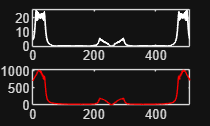

k = find(out.SciInfo_Valid,1);
fftData = out.SciInfo(k:end);

a = 1:FFT;
a = a';
subplot(2,1,1);
plot(a, fftData(1:FFT), 'w', 'linewidth', 1);
xlim([0 FFT])

specAvg =  floor(length(fftData)/FFT);
fftData_snr1 = fftData(1:specAvg*FFT);
fftData_snr2 = reshape(fftData_snr1, FFT, specAvg);

fftData_snr3 = sum(fftData_snr2,2);
subplot(2,1,2);
plot(a,fftData_snr3/10,'r')
xlim([0 FFT])